# Integrazione matrice di rotazione

Esercitazione di Meccanica dei Robot del 20/10/2021

clc; clear all;

% comandi per cambiare la formattazione grafica delle scritte nei grafici
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex');
set(groot, 'defaultTextInterpreter','latex');

% aggiungo al path tutte le cartelle necessarie
addpath(genpath(pwd))
addpath(genpath('..\Casadi'))

## Breve cenno ad alcuni metodi di integrazione

Dato un sistema di equazioni differenziali in tempo continuo 

$\dot x = f(x, t)$ con $x(0) = x_0$

vogliamo calcolarci un'approssimazione della soluzione $x(t_k)$ ai volori discreti del tempo $t_1,...,t_N$.

Definendo con $h = t_{k+1} - t_k$, per un metodo esplicito possiamo calcolarci l'approssimazione:


$$x_{k+1} = x_k + F(x_k, t_k, h, f)$$


mentre per un metodo implicito si ha


$$x_{k+1} = x_k + F(x_{k+1}, t_{k+1}, h, f)$$


Si definisce l'errore locale di troncamento come:


$$LTE = x(t_{k+1})-x_{k+1} $$


Un metodo si definisce di ordine$p$ se l'$LTE$è $O(h^{p+1})$

#### Alcuni metodi di integrazione

- Eulero in avanti (esplicito) ($p = 1$, numericamente 'instabile'):

            
$$x_{k+1} = x_k + hf(x_k, t_k)$$


- Eulero indietro (implicito) ($p=1$, numericamente 'stabile'):

            
$$x_{k+1} = x_k+ hf(x_{k+1}, t_{k+1})$$


- Runge Kutta 4 (esplicito) ($p = 4$):

            
$$x_{k+1} = x_k + \frac{h}{6}(f_1 + 2f_2 + 2f_3 + f_4)$$


            con

            
$$\matrix{
f_1 &= &f(x_k, t_k) \cr
f_2 &=& f\left(x_k + \frac{h}{2}f_1, t_k + \frac{h}{2}\right)\cr
f_3 &= &f\left(x_k + \frac{h}{2}f_2, t_k + \frac{h}{2}\right)\cr
f_4 &=& f(x_k + hf_3, t_k + h)
}$$


## Esempio di integrazione numerica dell'attrattore di Lorenz

Parametri dell'attrattore di Lorenz

sigma =    3;
beta  =    1;
rho   = 26.5;

Parametri di integrazione

t0 = 0;
t_end = 20;               % time horizon
dt = 0.025;               % integration time step
x0 = [1;1;1];             % initial state
steps = floor(t_end./dt); % number of integration steps

Modellazione dell'attrattore di Lorenz

import casadi.*
x = SX.sym('x', 3, 1);                   % casadi symbolic variable
xdot = [sigma.*(x(2) - x(1))            ;...
        rho.*x(1)    - x(1).*x(3) - x(2);...
        x(1).*x(2)   - beta.*x(3)      ];

Integrazione del sistema e plot dei risultati

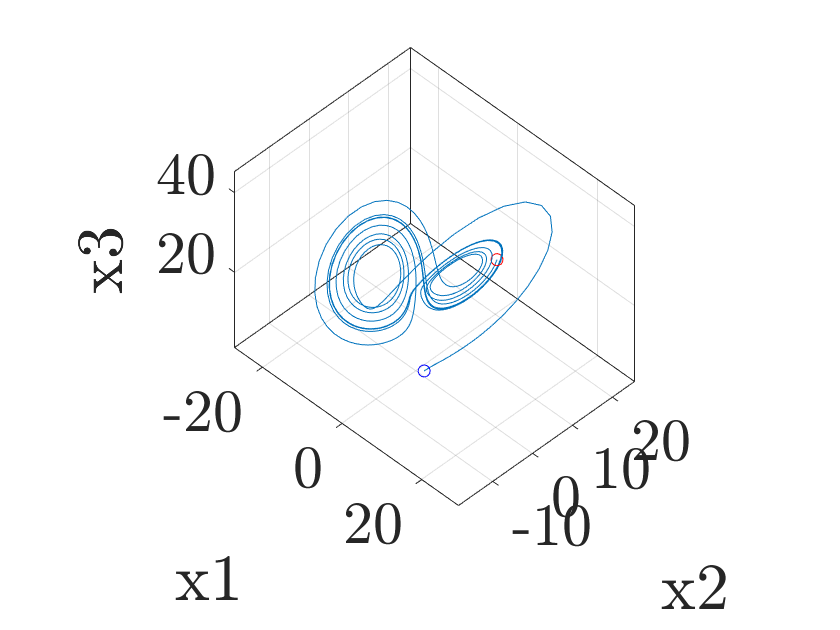

% Runge-Kutta 4-th order integrator
x_discrete = RK4(x, [], xdot, dt, t_end, x0, t0, []);
% ode45
% check function helper if the system has inputs, is time variant or more integration steps are required over the time interval

% plot the results
figure; hold on; axis equal; box on;rotate3d on;
grid on; view(45,45);
xlabel('x1')
ylabel('x2')
zlabel('x3')
set(gca, 'Fontsize', 30)
line(x_discrete(1, :), x_discrete(2, :), x_discrete(3, :))
line(x_discrete(1, 1), x_discrete(2, 1), x_discrete(3, 1), 'marker', 'o', 'color', 'b');
line(x_discrete(1, end), x_discrete(2, end), x_discrete(3, end), 'marker', 'o', 'color', 'r');

#### Creiamo un'animazione

% intialize figure
figure; hold on; axis equal; box on; grid on;
view(45, 25)
% initialize the plot object: the point and the trajecotry
point = line(gca, nan, nan, nan, 'marker', 'o', 'color', 'r');
trajectory = line(gca, nan(size(x_discrete(1,:))), nan(size(x_discrete(1,:))), nan(size(x_discrete(1,:))), 'color', 'b');
xlabel('x1')
ylabel('x2')
zlabel('x3')

% animate
for i = 1:steps
    set(point, 'XData', x_discrete(1, i), 'YData', x_discrete(2, i), 'ZData', x_discrete(3, i));
    trajectory.XData(i) = x_discrete(1, i);
    trajectory.YData(i) = x_discrete(2, i);
    trajectory.ZData(i) = x_discrete(3, i);

%     pause(0.01)
    drawnow

end

## Introduzione sulla parametrizzazione di una rotazione con asse e angolo

Una rotazione si può parametrizzare con le informazioni relative all'asse e l'angolo. I parametri sono 4:

$\underline{n}$, con vincolo $\underline{n}^T\underline{n} = 1$, e $\theta
$

La parametrizzazione si può esprimere in forma matriciale come:


$$R(\underline{n},\theta) =  \underline{n}\underline{n}^T+(I-\underline{n}\underline{n}^T)\cos{\theta} + \hat{n}\sin{\theta}$$


ed in forma estesa:


$$R(\underline{n}, \theta) =  \left[ \matrix{
n_x^2v_{\theta}+ \textrm{c}\theta & n_xn_yv_{\theta} - n_z\textrm{s}\theta & n_xn_zv_{\theta}+n_y\textrm{s}\theta \cr
n_xn_yv_{\theta} + n_z\textrm{s}\theta & n_y^2v_{\theta}+\textrm{c}\theta & n_yn_zv_{\theta}-n_x\textrm{s}\theta\cr
n_xn_zv_{\theta} - n_y\textrm{s}\theta &  n_yn_zv_{\theta}+n_x\textrm{s}\theta &n_z^2v_{\theta}+\textrm{c}\theta
}
\right]$$


dove $\textrm{c}\theta = \cos{\theta}; $ $\textrm{s}\theta = \sin{\theta}$; $v_{\theta} = 1 - \cos{\theta}$.

Dimostrazione rigorosa ed approfondimenti si possono recuperare dalle dispense e/o videolezione: https://www.youtube.com/watch?v=2QdjzPZzjQE

## Relazione tra la derivata della matrice di rotazione e velocità angolare:

#### Velocità angolare spatial

Definiamo con $R_{gl} $ una trasformazione di coordinate da $\{L\} $ a $\{G\}$ tale che


$$\underline p_g = R_{gl}\underline p_l$$


dalla definizione di matrice di rotazione sappiamo che 


$$R_{gl}R_{gl}^T = I$$


derivando rispetto al tempo:


$$\dot R_{gl}R_{gl}^T + R_{gl}\dot R_{gl}^T=0$$



$$\dot R_{gl}R_{gl}^T =  - (\dot R_{gl}R_{gl}^T)^T$$


dunque $\dot R_{gl}R_{gl}^T$ è una matrice anti simmetrica

Per un c.r. che ruota attorno ad un punto fisso (origine di $\{G\}$) è noto che


$$\underline\dot p_g=\underline\omega_{gl}^g\times\underline p_g= \hat{\omega}_{gl}^g\underline p_g$$


sappiamo anche che 

$\underline\dot p_g= \dot R_{gl}\underline p_l$   e    $\underline p_l = R_{gl}^T\underline p_g$

sostituendo si ottiene


$$\underline\dot p_g=\hat{\omega}_{gl}^g\underline p_g = \dot R_{gl}R_{gl}^T\underline p_g$$


la velocità angolare spatial ( espressa in componenti di $\{G\}$) è 


$$\hat \omega_{gl}^g = \dot R_{gl}R_{gl}^T$$


Queste sono le formule di Poisson scritte in modo compatto:

data la definizione della matrice di rotazione


$$R_{gl} = \left[\matrix{
i_{x} & j_{x} & k_{x} \cr
i_{y} & j_{y} & k_{y} \cr
i_{z} & j_{z} & k_{z} 
} \right]$$


e utilizzando le formule di Poisson (i.e.  $\dot{\underline{i}} = \underline{\omega}\times \underline{i} = \hat{\omega}\underline i$) si può facilmente ritrovare:


$$$\dot{R_{gl}} = \hat{\omega}_{gl}^gR_{gl}  $$$


#### Velocità angolare body

Potrei esprimere gli elementi della velocità angolar anche in terna locale $\{L\}$ (body)

partendo da:


$$\underline\dot p_g= \dot R_{gl}\underline p_l$$
 

ed applicando una trasformazione di coordinate posso scrivere


$$\left[ \underline \dot p_g\right]_l = R_{gl}^T\dot R_{gl}\underline p_l$$


In terna del c.r. si scriverebbe:


$$\left[ \underline \dot p_g\right]_l = \underline \omega_{gl}^l \times \underline p_l = \hat{\omega}_{gl}^l\underline p_l$$


dunque 


$$\hat{\omega}_{gl}^l = R_{gl}^T\dot R_{gl}$$


quindi se usassi la velocità angolare body, l'eq. differenziale si scriverebbe:


$$\dot R_{gl}=R_{gl}\hat{\omega}_{gl}^l$$


## Integrazione di un sistema in rotazione

Consideriamo un corpo che ruota attorno all asse z

omega = [0;0;1];             % velocità angolare

la soluzione analitica delle eq.differenziali

$$\dot{R_{gl}} = \hat{\omega}R_{gl}  $$,

 per $\underline{\omega}$ costante, è


$$R_{gl}(t) = e^{\hat{\omega}t}R_{gl}(0)$$


Il vettore velocità angolare si può scrivere come:


$$\omega = \underline{n}\|\omega\|$$


e quindi

$\hat{\omega} t= \hat{n}\|\omega\| t = \hat{n}\theta$; la rotazione è parametrizzabile con asse e angolo

Applicando la formula di Rodriguez (nota: $\underline{n}\underline{n}^T-I = \hat{n}^2$):


$$R_{gl}(t) = I_{3\times3} + \hat{n}\sin{(\|\omega\|t)} + \hat{n}^2 \left( 1-\cos{(\|\omega\|t)} \right)R_0$$


ax = omega./vecnorm(omega);  % asse di rotazione
norm_omega = vecnorm(omega); % modulo velocità angolare
R0 = eye(3);                 % orientazione iniziale
R = @(t) rodriguezAxisAngle(ax, norm_omega.*t)*R0;
% R = @(t) rotZ(norm_omega.*t)*R0; % in questo semplice caso è banalmente una rotazione attorno a z

t_end = 20;
t0 = 0;
dt = 0.05;
t = 0:dt:20;
steps = length(t);
% soluzione esatta R(t_k)
Rsol = reshape(cell2mat(arrayfun(R, t, 'UniformOutput', false)), 3, 3, steps);

### Testiamo l'integrazione con Eulero in avanti

Lo schema di integrazione con Eulero in avanti con $h$ come passo di integrazione:


$$R_{k+1} = \hat{\omega}R_{k}\cdot h + R_{k} = (I + \hat{\omega}h)R_k$$


Osservazione: se si calcola il determinante di $R_{1}$ al primo passo di integrazione

$\textrm{det}(R_{1}) = \textrm{det}(I + \hat{\omega}h)\textrm{det}(R_0) = 1+ (\|\omega\|h)^2$  : $R_{1}$ non è più un oggetto di SO3 !!!

prendiamo gli elementi di R ed integriamoli nel tempo

import casadi.*
R = SX.sym('R', 3, 3); % matrice di rotazione simbolica con casadi
x = R(:);
f = hat(omega)*R;      % right hand side 
f = f(:);
x0 = R0(:);

Rsol_FE = reshape(forwardEuler(x, [], f, dt, t_end, x0, t0, []), 3, 3, steps);

#### Costruiamo un dodecaedro a cui applichiamo la matrice di rotazione nel tempo

[Vertices, Faces] = platonic_solids(5, 1, false);

#### Animazione con confronto tra soluzione analitica ed il metodo di Eulero avanti

animateRotation(Vertices, Faces, Rsol_FE, Rsol, 'alphaExact', 0.45, 'alphaIntegrated', 0.2, 'Visible', 'on');

Invalid or deleted object.

Error in animateRotation (line 86)
    local_frame{1}(1).XData = axpt(1,1:2);    % update axes points

#### Decomposizione ai valori singolari

Data una matrice $A$ essa si può fattorizzare nel seguente modo:

$A = U\Sigma V^*$,

$U $ è la matrice dei vettori singolari sinistri, ovvero autovettori di $AA^*$

$V$ è  la matrice dei vettori singolari destri, ovvero autovettori di $A^*A$

$\Sigma $ è una matrice diagonale che contiene gli autovalori non nulli di $A^*A $ o $AA^*$ sotto radice

[U_FE, Sigma_FE, V_FE] = svd(Rsol_FE(:, :, end));
[U, Sigma, V] = svd(Rsol(:, :, end));
Sigma_FE

Sigma_FE =     1.6477         0         0
         0    1.6477         0
         0         0    1.0000


Sigma

Sigma =      1     0     0
     0     1     0
     0     0     1


% [E, R] = ERfromAffineTransform(Rsol_FE(:, :, end));
% E
% R

gli autovalori di  $\Sigma_{FE}$ non sono unitari, ciò implica una deformazione del corpo nelle prime due direzioni principali.

#### Applicazione del metodo di integrazione di Eulero indietro

Rsol_BE = reshape(backwardsEuler(x, [], f, dt, t_end, x0, t0, []), 3, 3, steps);

Vediamo l'animazione

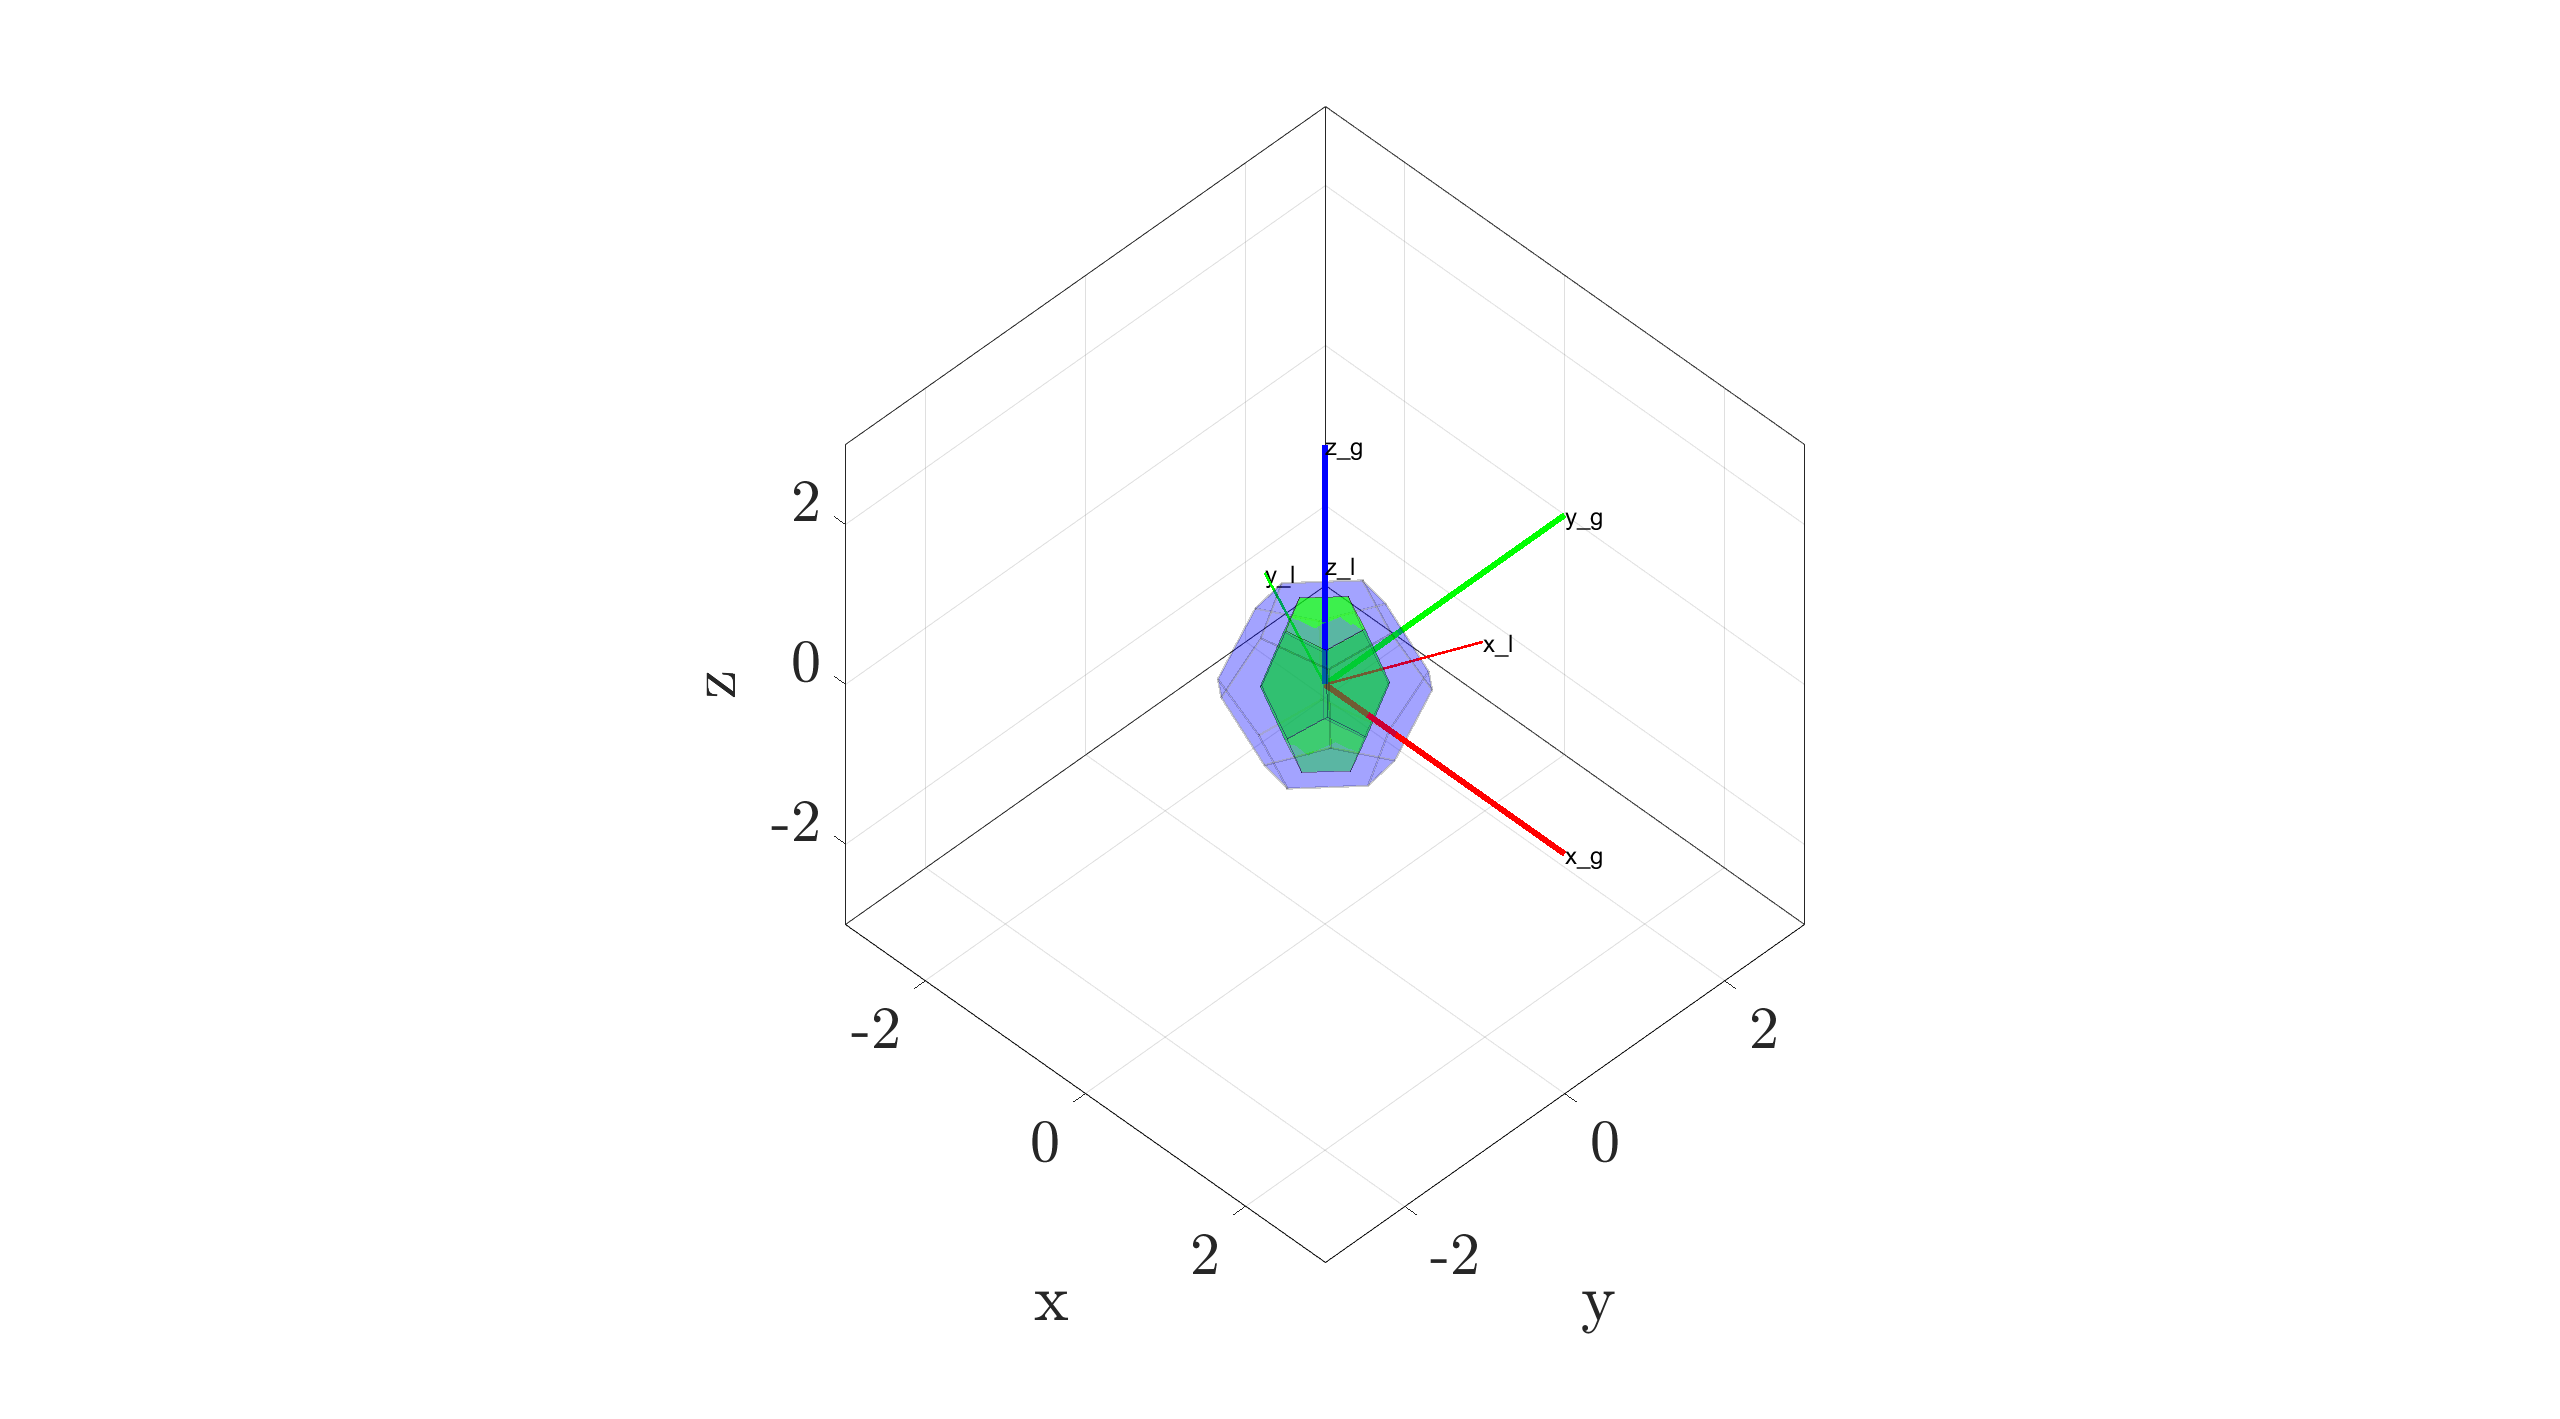

animateRotation(Vertices, Faces, Rsol_BE, Rsol, 'alphaExact', 0.2, 'alphaIntegrated', 0.45);

Calcoliamo il determinante di $R_{1}$ al primo passo di integrazione


$$R_1 = R_0 + h\hat{\omega}R_1 \Rightarrow R_1 = (I-h\hat{\omega})^{-1}R_0$$


$\textrm{det}(R_{1}) = \textrm{det}((I - \hat{\omega}h)^{-1})\textrm{det}(R_0) = 
\frac{1}{1+ (\|\omega\|h)^2}$  : $R_{1}$ non è più un oggetto di SO3 !!!

Si osserva però che $\frac{1}{1+ (\|\omega\|h)^2} < (\|\omega\|h)^2$ quindi si comporta meglio del metodo di Eulero in avanti.

#### Applicazione del metodo di integrazione di Runge Kutta 4° ordine

inserire formule schema

Rsol_RK = reshape(RK4(x, [], f, dt, t_end, x0, 0, []), 3, 3, steps);

Vediamo l'animazione

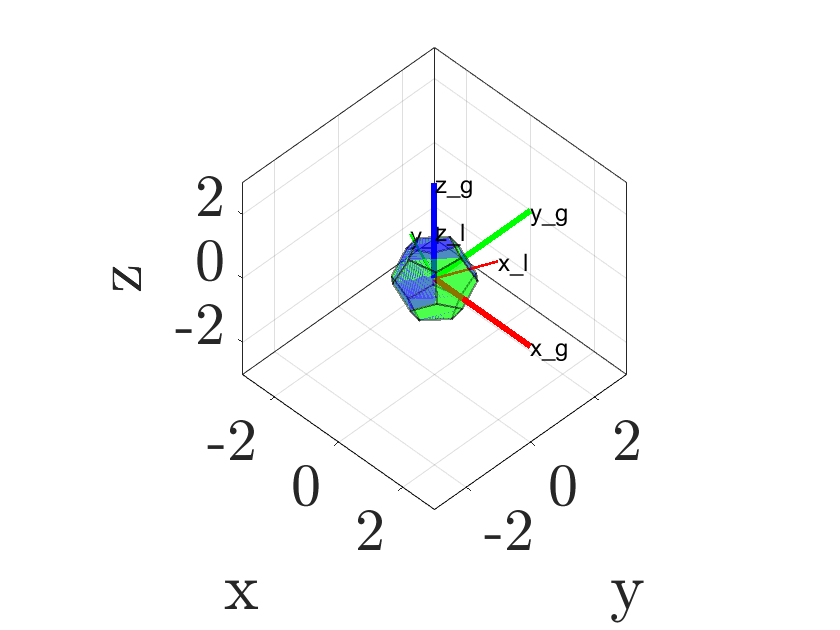

animateRotation(Vertices, Faces, Rsol_RK, Rsol, 'alphaExact', 0.45, 'alphaIntegrated', 0.45);

#### Analizziamo la norma Frobenius ( $|A|^{2} = \sum^{n}_{i=1} \sum^{n}_{j=1} a_{ij}^2$ ) della differenza delle soluzioni numeriche e quella analitica: $| R_{reale} - R_{num}|$

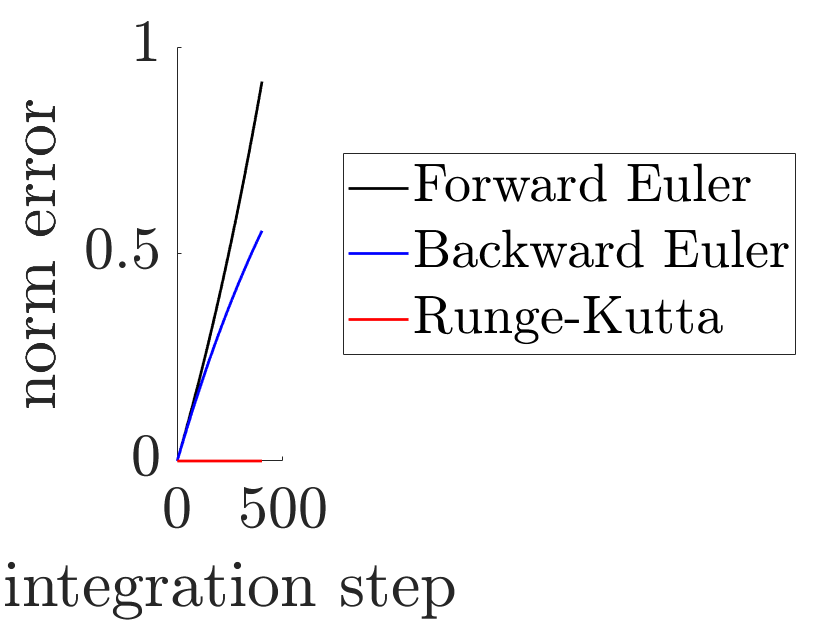

figure; hold on;
error_FE = vecnorm(reshape(Rsol - Rsol_FE, 9, steps), 2, 1);
error_BE = vecnorm(reshape(Rsol - Rsol_BE, 9, steps), 2, 1);
error_RK = vecnorm(reshape(Rsol - Rsol_RK, 9, steps), 2, 1);

line(gca, 1:steps, error_FE, 'color', 'k', 'Linewidth', 1.4);
line(gca, 1:steps, error_BE, 'color', 'b', 'Linewidth', 1.4);
line(gca, 1:steps, error_RK, 'color', 'r', 'Linewidth', 1.4);
xlabel('integration step')
ylabel('norm error')
legend('Forward Euler', 'Backward Euler', 'Runge-Kutta', 'location', 'eastoutside')
set(gca, 'Fontsize', 30)

## Proiezione su SO(3) tramite la decomposizione SVD

Idea di base:

Per ogni passo di integrazione calcolato determiniamo la  matrice di rotazione $\tilde{R}_{k} \in \textrm{SO}(3)$ che meglio approssima  $R_{k} \notin \textrm{SO}(3)$  minimizzando la norma di Frobenius $|\tilde{R}_{k}-R_{k}|$. Si può dimostrare che la soluzione a tale problema è:


$$\tilde{R_{k}} = U\left[ \matrix{
1 & 0 & 0 \cr
0 & 1 & 0 \cr
0 & 0 & \det{(UV^T)}
} \right] V^T$$


dove U e V sono le matrici singolari di $R_k = U\Sigma V^T$.

Osservazioni:

- $\Sigma
$ contiene le informazioni sulla distorsione dello spazio generata da $R_k$, quindi si può rimuovere;

- U e V conengono le informazioni sulla rotazione dello spazio generato da $R_k
$, quindi le conserviamo;

- se l'errore è tale che $\det(R_k)<0$, dobbiamo ripristinare il giusto segno al determinante di $\tilde{R}_k$ con il valore di $\det{(UV^T)$

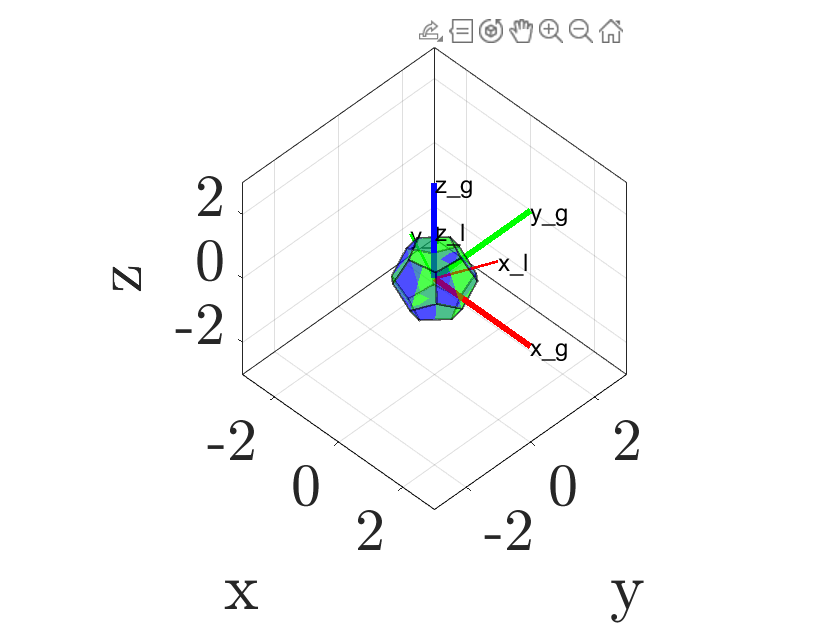

Rsol_FE_SO3 = toSO3(Rsol_FE);
animateRotation(Vertices, Faces, Rsol_FE_SO3, Rsol, 'alphaExact',0.45, "alphaIntegrated",0.45);

#### Analizziamo la norma Frobenius degli errori

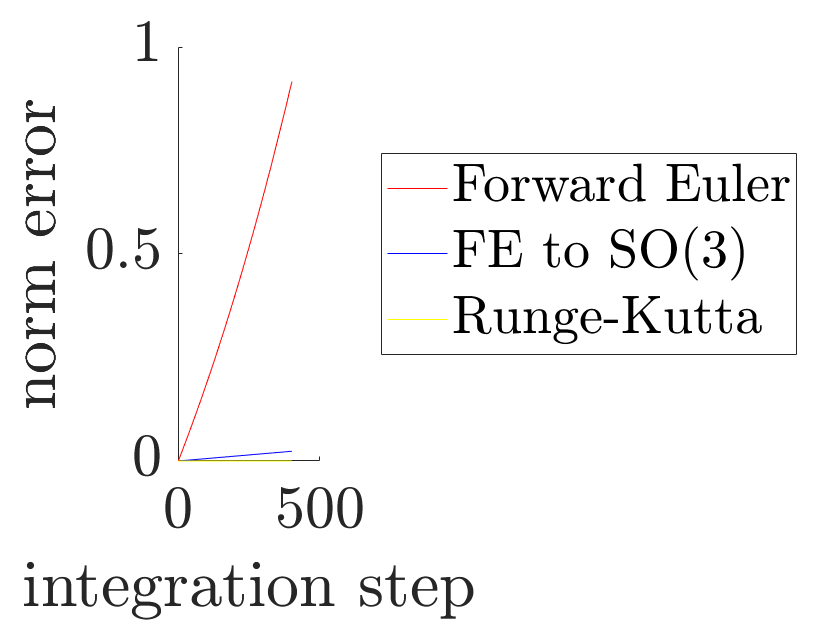

error_FE_SO3 = vecnorm(reshape(Rsol - Rsol_FE_SO3, 9, steps), 2, 1);
figure; hold on;
line(gca, 1:steps, error_FE, 'color', 'r');
line(gca, 1:steps, error_FE_SO3, 'color', 'b');
line(gca, 1:steps, error_RK, 'color', 'y');
xlabel('integration step')
ylabel('norm error')
legend('Forward Euler', 'FE to SO(3)', 'Runge-Kutta', 'location', 'eastoutside')
set(gca, 'Fontsize', 30)

## Rotazione con parametrizzazione di SO(3) yaw-pitch-roll

Un ulteriore approccio al problema è quello di utilizzare una parametrizzazione in SO(3) ed integrarne direttamente i parametri

Creiamo le variabili degli angoli di rotazione di una parametrizzazione ZYX

import casadi.*
psi = SX.sym('psi')

psi = psi

theta = SX.sym('theta')

theta = theta

phi = SX.sym('phi')

phi = phi

costruzione matrice di orientazione 

Rypr = Function('Rfun', {psi, theta, phi}, {rotZ(psi)*rotY(theta)*rotX(phi)}) % utilizziamo la casadi function

Rypr = Rfun:(i0,i1,i2)->(o0[3x3]) SXFunction

testiamo la matrice di rotazione

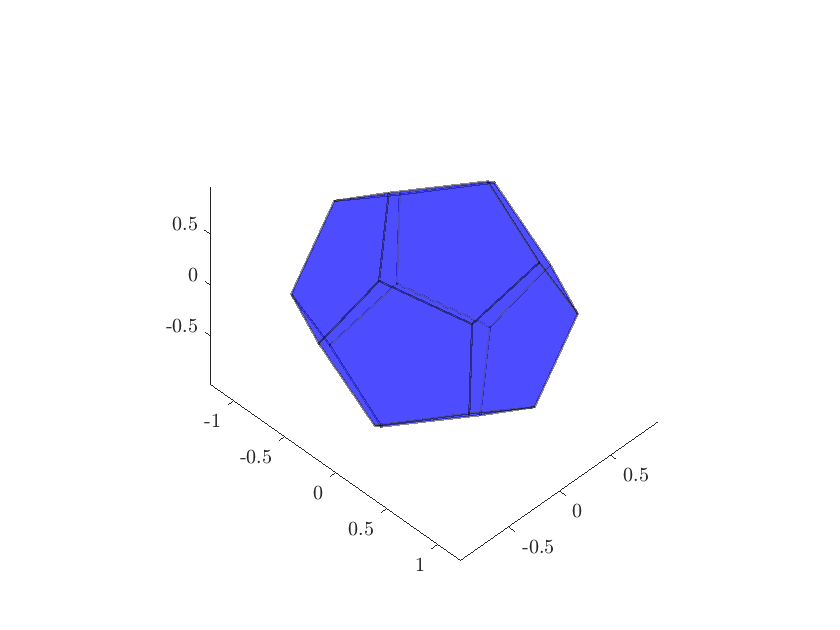

figure; hold on; axis equal
view(45, 45)
transform = hgtransform(gca);
patch(transform, 'Vertices', Vertices, 'Faces', Faces, 'FaceColor',"b", "EdgeColor",'k', 'facealpha', 0.45, 'edgealpha', 0.45, 'linewidth', 1.1);
transform.Matrix = RpTohomogeneous(full(Rypr(0.1, 0.3, 0.1)), [0;0;0]);

Ragruppiamo i parametri in un vettore: $\underline{\alpha} = \left[ 
\matrix{\psi & \theta &\phi }
\right]^T$ e scriviamo la relazione tra tali parametri e la velocità angolare


$$\matrix{\underline{\omega} &= &(\dot{R}R^T)\check  \cr
 &= &\left(\frac{\partial R}{\partial \underline{\alpha}} \dot{\underline{\alpha}}R^T\right)\check \cr
&=& \left(\left(   \sum_{i=1}^3 \frac{\partial R}{\partial \alpha_{i}}  \dot{\alpha}_{i}  \right)R^T\right) \check \cr
&=& \sum_{i=1}^3\left(  \frac{\partial R}{\partial \alpha_i} R^T \right)\check{ } \dot{\underline{\alpha}} \cr
&=& \left[
\matrix{\left( \frac{\partial R}{\partial \alpha_1}R^T\right)\check{} &  \left( \frac{\partial R}{\partial \alpha_1}R^T\right)\check{}  &\left( \frac{\partial R}{\partial \alpha_1}R^T\right)\check{} 
}
\right]\dot{\underline{\alpha}}\cr
&=& J_s \dot{\underline{\alpha}}
}


$$


Abbiamo definito così una mappa lineare (matrice Jacobiana) tra la velocità angolare $\underline{\omega}$ e le derivate della parametrizzazione di SO(3) $\dot{\underline{\alpha}}$. Si può invertire adesso la relazione (attenzione alle configurazioni singolari):

$\dot{\underline{\alpha}} = J_s^{-1}\underline{\omega}$.

Queste sono 3 eq. differenziali che si possono integrare numericamente.

Calcoliamo quindi lo jacobiano con casadi:

import casadi.*
Rypr_expr = Rypr(psi, theta, phi);
alpha = vertcat(psi, theta, phi);
Js = zeros(3, 3, 'casadi.SX');
for i = 1:3
    Js(:, i) = vecForm(reshape(jacobian(Rypr_expr, alpha(i)), 3, 3)*Rypr_expr.');
end
Js_inv = solve(Js, eye(Js.size1(), 'casadi.SX'));
% Js_inv = inv(EulZYXToSpatialJac(psi, theta, phi));

Definiamo la ODE ed integriamo con Eulero in avanti


alpha_dot = Js_inv*omega;
alpha_sol_FE = forwardEuler(alpha, [], alpha_dot, dt, t_end, [0;0;0], 0, []);

Ricaviamoci la matrice di rotazione a partire dai parametri integrati

Rsol_ypr = reshape(cell2mat(arrayfun( @(psi, theta, phi) full(Rypr(psi, theta, phi)), alpha_sol_FE(1,:), alpha_sol_FE(2,:), alpha_sol_FE(3,:), 'UniformOutput', false)), 3, 3, steps);

Riproduciamo l'animazione

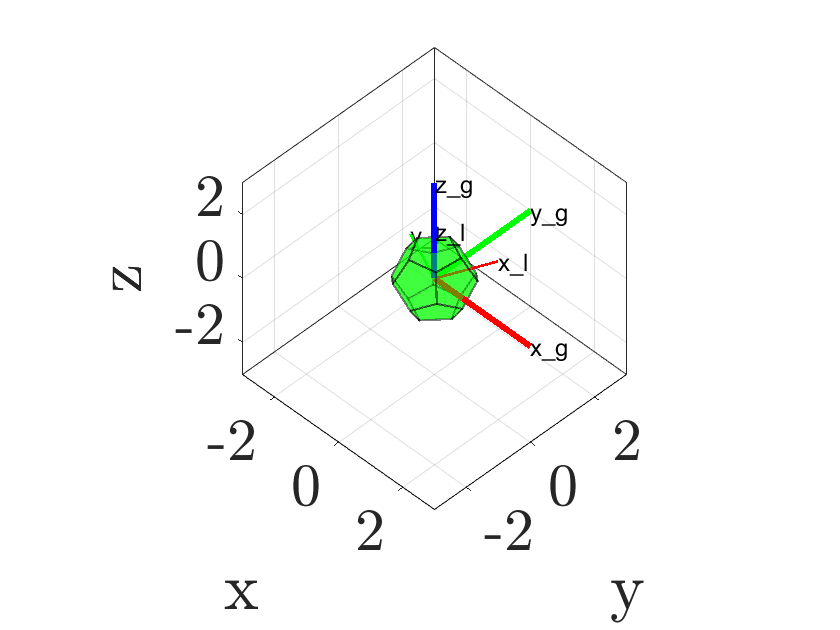

animateRotation(Vertices, Faces, Rsol_ypr, Rsol);

Verifichiamo l'errore con la norma di Frobenius della matrice differenza:

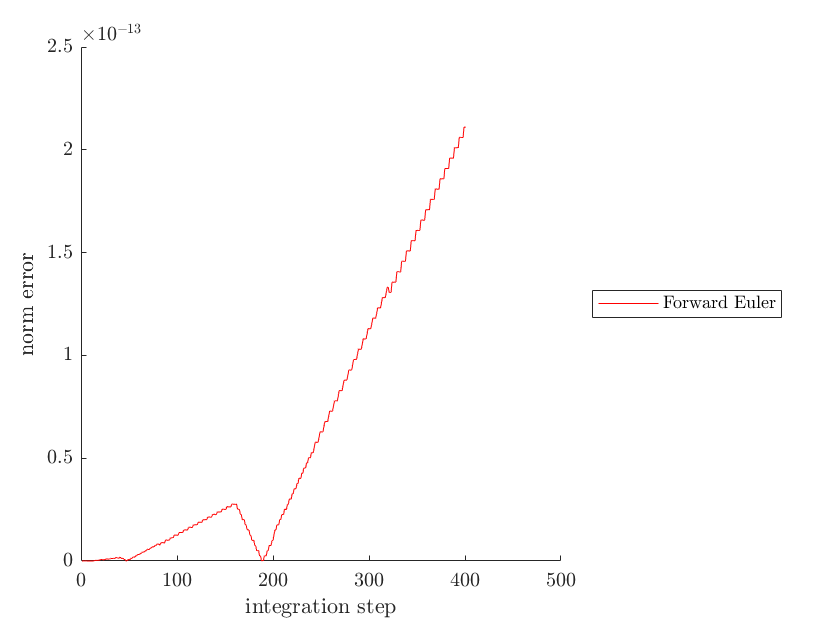

error_ypr = vecnorm(reshape(Rsol - Rsol_ypr, 9, steps), 2, 1);
figure; hold on;
line(gca, 1:steps, error_ypr, 'color', 'r');
xlabel('integration step')
ylabel('norm error')
legend('Forward Euler', 'location', 'eastoutside')

Anche con un'integrazione numerica poco accurata abbiamo ottenuto una soluzione esatta! Perchè?

Cosa succede se cambiamo la direzione di $\underline{\omega}$ ?

new_omega = [1;1;1]./vecnorm([1;1;1]);
new_ax = new_omega./vecnorm(new_omega);
new_norm_omega = vecnorm(new_omega);

alpha_dot_new = Js_inv*new_omega;
alpha_sol_FEnew = forwardEuler(alpha, [], alpha_dot_new, dt, t_end, [0;0;0], 0, []);
Rsol_yprnew = reshape(cell2mat(arrayfun( @(psi, theta, phi) full(Rypr(psi, theta, phi)), alpha_sol_FEnew(1,:), alpha_sol_FEnew(2,:), alpha_sol_FEnew(3,:), 'UniformOutput', false)), 3, 3, steps);

calcoliamo la soluzione analitica

Rnew = @(t) rodriguezAxisAngle(new_ax, new_norm_omega.*t)*R0;
Rsolnew = reshape(cell2mat(arrayfun(Rnew, t, 'UniformOutput', false)), 3, 3, steps);

Riproduciamo l'animazione

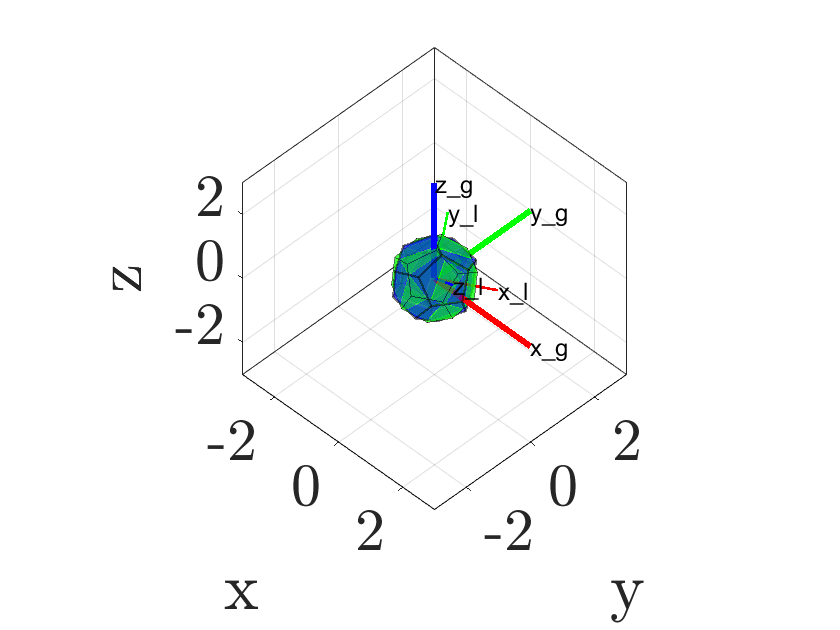

animateRotation(Vertices, Faces, Rsol_yprnew, Rsolnew);

Verifichiamo l'errore:

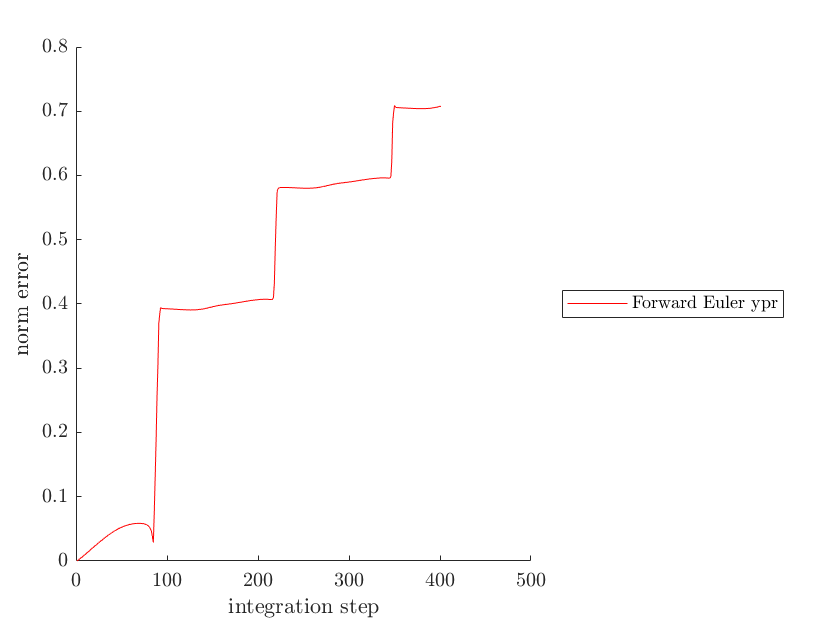

error_ypr = vecnorm(reshape(Rsolnew - Rsol_yprnew, 9, steps), 2, 1);
figure; hold on;
line(gca, 1:steps, error_ypr, 'color', 'r');
xlabel('integration step')
ylabel('norm error')
legend('Forward Euler ypr',  'location', 'eastoutside')

Analizziamo graficamente la nuova RHS della ODE

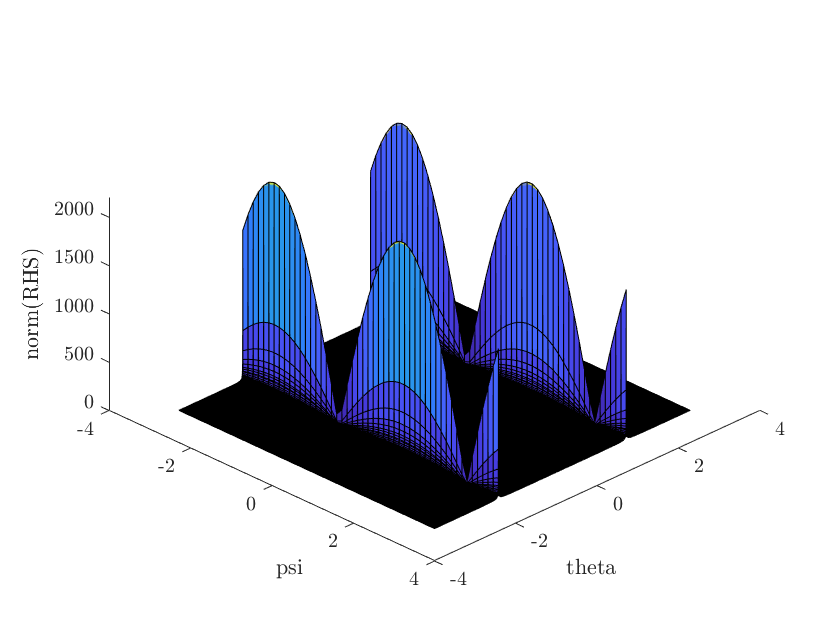

import casadi.*
npsi = 50;
ntheta = 3000;
[psigrid, thetagrid] = meshgrid(linspace(-pi, pi, npsi), linspace(-pi, pi, ntheta));
RHS_fun = Function('rhs', {psi, theta, phi}, {alpha_dot_new});
RHSgrid = reshape(vecnorm(full(RHS_fun(psigrid(:).', thetagrid(:).', 0.*thetagrid(:).'))).', ntheta, npsi);


figure; hold on; view(45, 45)
surface(psigrid, thetagrid, RHSgrid)
xlabel('psi')
ylabel('theta')
zlabel('norm(RHS)')

## Introduzione sulla parametrizzazione coi quaternioni (parametri di Eulero)

Il quaternione è un oggetto matematico che può essere considerato come la generalizzazione di un numero complesso:


$$Q = q_0 + q_1\underline{i} + q_2\underline{j}+q_3\underline{k} = [q_0, \underline{q}]$$


La sua algebra segue le seguenti regole:

- 
$$\underline{i}\cdot\underline{i}  = 
\underline{j}\cdot\underline{j}  = 
\underline{k}\cdot\underline{k}  = -1$$


- $\underline{i}\cdot{}\underline{j} = - \underline{i}\cdot{}\underline{j} = \underline{k}$;  $\underline{j}\cdot{}\underline{k} = - \underline{k}\cdot{}\underline{j} = \underline{i}$; $\underline{k}\cdot{}\underline{i} = - \underline{i}\cdot{}\underline{k} = \underline{j}$

- dunque anche $\underline{i}\cdot{}\underline{j} \cdot  \underline{k}= - 1$

Utilizando le regole appena riportate si può scrivere il prodotto tra due quaternioni $Q =[q_0, \underline{q}]$ e $P =[p_0, \underline{p}]$ utilizzando la notazione moderna


$$Q\cdot P = \left[ 
q_0p_0 - \underline q^T\underline p, q_0\underline p + p_0 \underline q + \hat{\underline q}\underline p
\right]$$


Il coniugato di un quaternione è definito come $Q^{*} = [q_0, -\underline {q}]$

Come si legano i quaternioni alle rotazioni? I quaternioni unitari, ovvero caratterizzati da $\|Q\| = 1$, sono legati alla parametrizzazione asse angolo $(\underline{n}, \theta)$ nel seguente modo:

$Q_R = \left[\cos{\frac{\theta}{2}}, \underline{n}\sin{\frac{\theta}{2}} \right]$,

viceversa, dato un quaternione unitario $Q_u = \left[ q_0, \underline{q}\right]$, tale che $q_0^2+q_1^2+q_2^2+q_3^2+q_4^2 = 1$, i parametri asse ed angolo corrispondenti sono:

$\theta = 2\arccos(q_0)$, $\underline{n} = \left\{\matrix{\frac{1}{\sin{\frac{\theta}{2}}}\underline{q}, \textrm{ se }  \theta \neq 0\cr
\underline{0} \textrm{ altrimenti} }$.

La composizione di rotazioni è analoga alle matrici di rotazione:

se una rotazione è composta da 


$$R_3 = R_1R_2$$


la rappresentazione con i quaternioni unitari risulta semplicemente

$Q_{R_3} = Q_{R_1}Q_{R_2}$.

La matrice di rotazione è esprimibile in funzione dei parametri di Eulero:


$$R(q_0, \underline{q}) = I + 2\hat{\underline q}\left(q_0I + \hat{\underline q}\right)$$


Se si vuole utilizzare i quaternioni per ruotare direttamente punti (per es. il punto $\underline{p}$), si crea prima una rappresentazione 'a quaternioni' di un vettore:


$$P = \left[0, \underline{p}]$$


e lo si ruota così:


$$P' = Q_uPQ_u^*$$


Approfondimenti e dettagli si possono trovare sulle dispense e/o videolezione: https://www.youtube.com/watch?v=KsZ1c00czKU

#### Relazione tra i parametri di Eulero e la velocità angolare:

dalla definizione di velocità angolare spatial:


$$\hat{\omega}^s = \dot{R}R^T$$


ed esprimendo la rotazione coi parametri di Eulero,  $\underline\beta = \left[\matrix{
 \beta_0 &\underline{\beta}
}
\right]^T$, è possibile ricavarsi la matrice jacobiana tra la velocità angolare ed i suddetti parametri:

$\underline{\omega}^s = (\dot R R^T)\check{} =  G\underline{\dot{\beta}}$,

con $G = 2\left[\matrix{
-\underline{\beta} |&I\beta_0+\hat{\underline\beta}
}
 \right] \in \mathbb{R}^{3\times4}$.

La relazione inversa è definita invece da:


$$\underline\dot\beta =L\underline\omega^s$$


con $L = \frac{1}{2}\left[\matrix{
-\underline\beta^T \cr
\hline 
I\beta_0 - \hat\underline\beta

}\right] \in \mathbb{R}^{4\times3}$

lo jacobiano tra la velocità angolare body ed i parametri di Eulero si possono ricavare allo stesso modo partendo da


$$\hat{\omega}^b = R^T\dot R$$


fare come esercizio

## Rotazione coi parametri di Eulero

q = SX.sym('q', 4, 1);                        % vettore dei parametri di Eulero
q_dot = EulParSpatialJacInv(q)*new_omega;     % RHS ODE
q0 = [1;0;0;0];                               % parametri iniziali
quat_sol_FE = forwardEuler(q, [], q_dot, dt, t_end, q0, t0, []); % integrazione

convertiamo i parametri di Eulero in matrici di rotazione

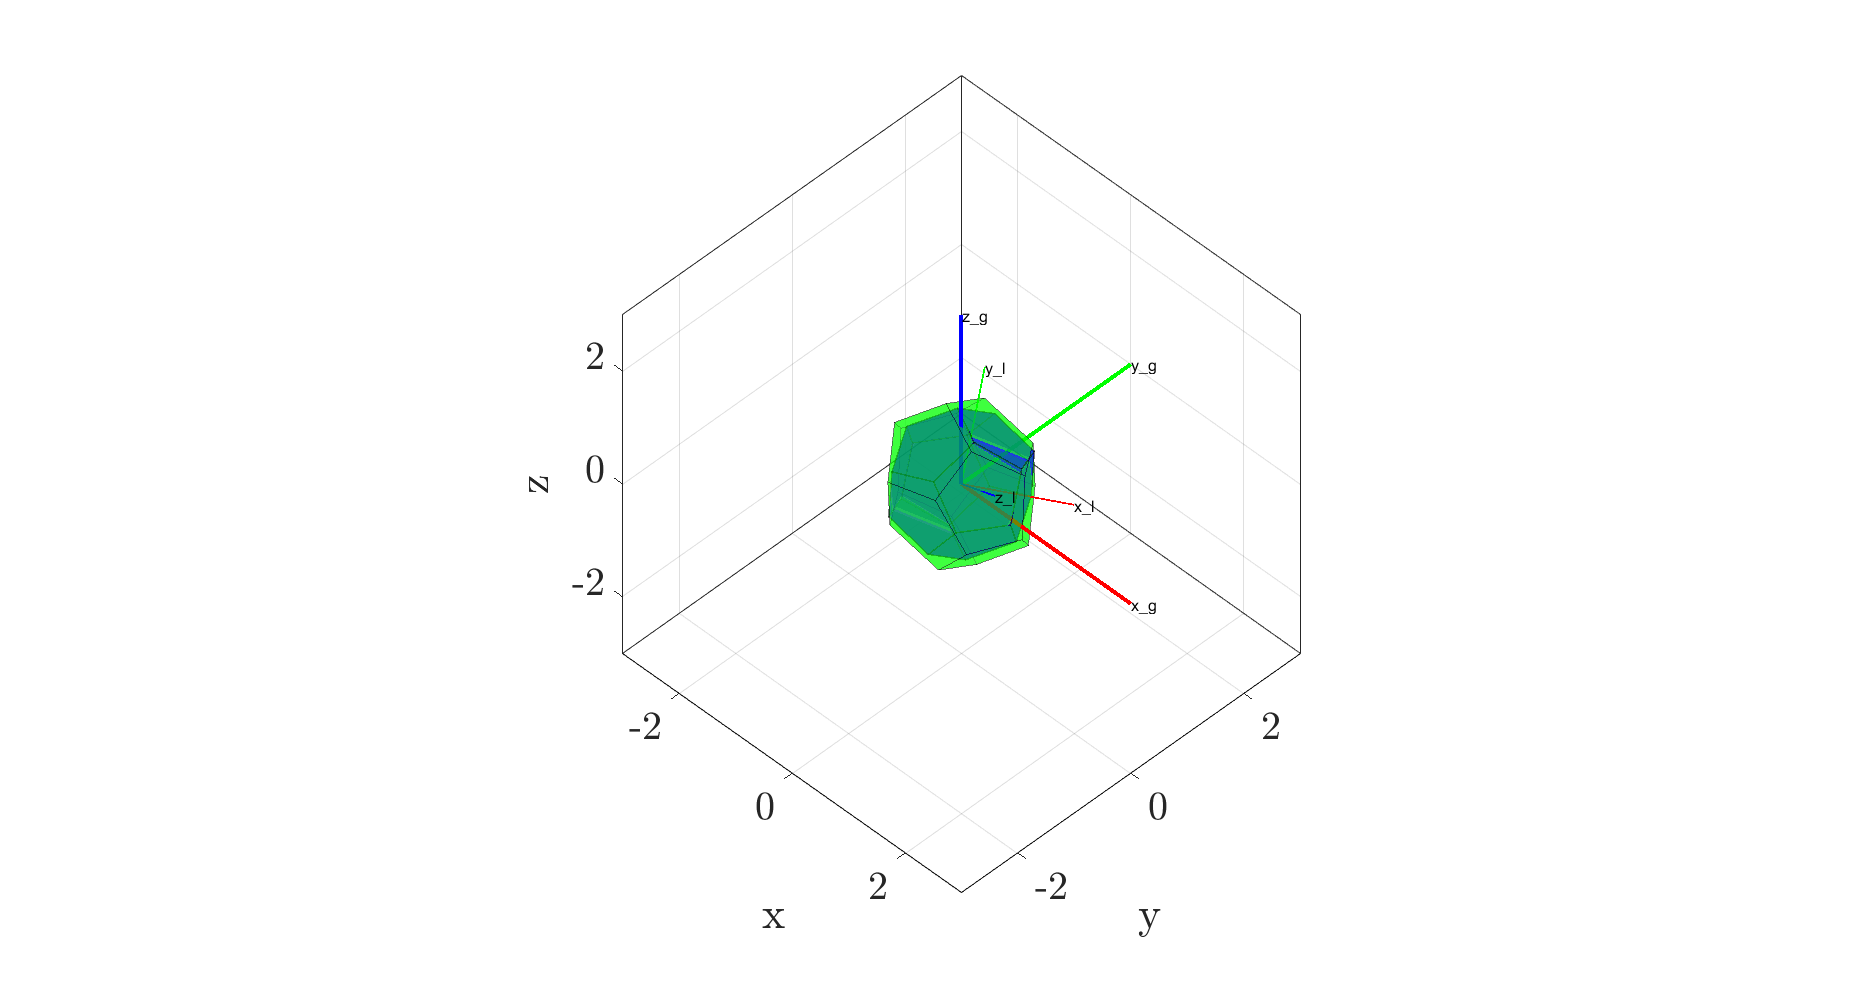

Rsol_quat = reshape(cell2mat(arrayfun( @(q1,q2,q3,q4) quatToRot([q1;q2;q3;q4]), quat_sol_FE(1,:), quat_sol_FE(2,:), quat_sol_FE(3,:), quat_sol_FE(4,:), 'UniformOutput', false)), 3, 3, steps);
animateRotation(Vertices, Faces, Rsol_quat, Rsolnew);

proiettiamo i quaternioni integrati nel manifold dei quaternioni unitari

quat_sol_norm = quat_sol_FE./vecnorm(quat_sol_FE);
Rsol_quat_norm = reshape(cell2mat(arrayfun( @(q1,q2,q3,q4) quatToRot([q1;q2;q3;q4]), quat_sol_norm(1,:), quat_sol_norm(2,:), quat_sol_norm(3,:), quat_sol_norm(4,:), 'UniformOutput', false)), 3, 3, steps);
animateRotation(Vertices, Faces, Rsol_quat_norm, Rsolnew);

#### Metodo di stabilizzazione di Baumgarte

Tale metodo prevede di aggiungere una dinamica fittizzia all'equazione differenziale. Questo termine smorza gli errori di integrazione in modo che la soluzione converga al manifold dei quaternioni unitari.

gamma_q = 17;
q_dot = EulParSpatialJacInv(q)*new_omega + gamma_q.*(1./sum(q.^2) - 1).*q;       % RHS ODE
quat_sol_FE_stab = RK4(q, [], q_dot, dt, t_end, q0, t0, []);                     % integrazione

Rsol_quat_stab = reshape(cell2mat(arrayfun( @(q1,q2,q3,q4) quatToRot([q1;q2;q3;q4]), quat_sol_FE_stab(1,:), quat_sol_FE_stab(2,:), quat_sol_FE_stab(3,:), quat_sol_FE_stab(4,:), 'UniformOutput', false)), 3, 3, steps);
animateRotation(Vertices, Faces, Rsol_quat_stab, Rsolnew);

Invalid or deleted object.

Error in animateRotation (line 86)
    local_frame{1}(1).XData = axpt(1,1:2);    % update axes points

Analizziamo gli errori

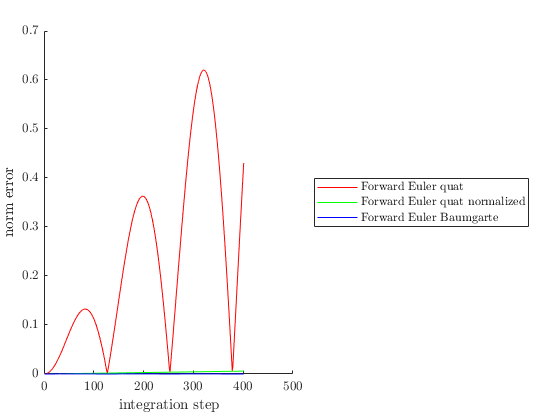

error_quat = vecnorm(reshape(Rsolnew - Rsol_quat, 9, steps), 2, 1);
error_quat_norm = vecnorm(reshape(Rsolnew - Rsol_quat_norm, 9, steps), 2, 1);
error_quat_stab = vecnorm(reshape(Rsolnew - Rsol_quat_stab, 9, steps), 2, 1);
figure; hold on;
line(gca, 1:steps, error_quat, 'color', 'r');
line(gca, 1:steps, error_quat_norm, 'color', 'g');
line(gca, 1:steps, error_quat_stab, 'color', 'b');
xlabel('integration step')
ylabel('norm error')
legend('Forward Euler quat', 'Forward Euler quat normalized', 'Forward Euler Baumgarte','location', 'eastoutside')